%ecModels DEMO
%
%  - Enzyme-constrained model exploration
%  - The role of enzyme constraints in growth simulations
%  - Growth on different carbon sources
%  - Crabtree effect simulation
%  
%  based on the latest
%  version of ecYeastGEM (GitHub: https://github.com/SysBioChalmers/GECKO)
%
% Ivan Domenzain.	Last modified 2020-02-09

## Enzyme-constrained model exploration

The most connected enzyme is: prot_P34756


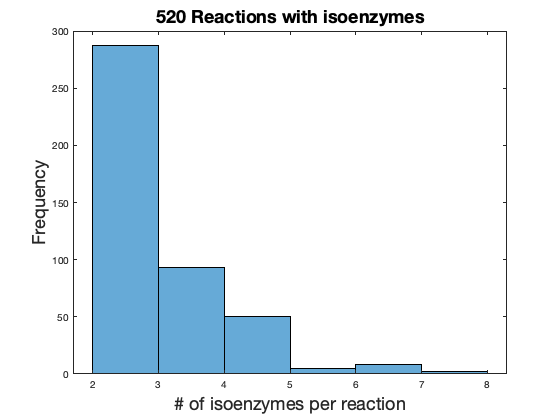

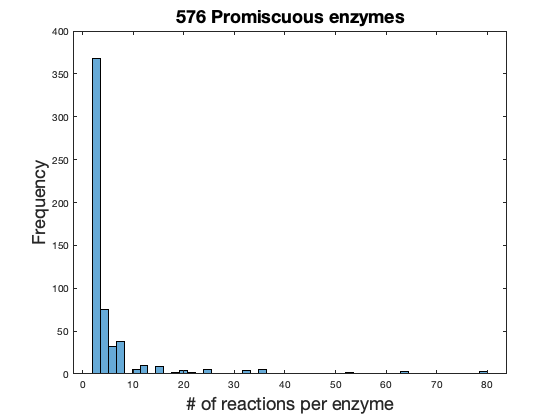

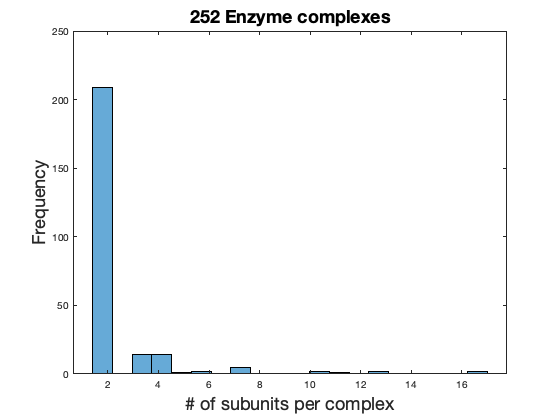

%Load ecModel with total protein pool constraint
load('models/ecYeastGEM.mat');
%Load original model (yeastGEM)
load('models/yeastGEM.mat');
%Get the total number of promiscuous enzymes isoenzymes and rxns with Kcats
cd complementary
[isoEnzymes,Promiscuous,Complexes,RxnWithKcat] =  rxnCounter(ecModel,model);

## Growth rate vs Glucose uptake rate

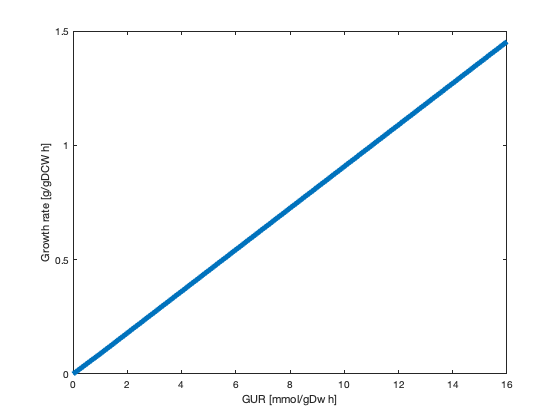

%Find relevant reaction positions first
growthIndex   = strcmpi(model.rxnNames,'growth');
growthIndexEC = strcmpi(ecModel.rxnNames,'growth');
glucIN        = model.rxns{strcmpi(model.rxnNames,'D-glucose exchange')};
glucIndex     = strcmpi(model.rxnNames,'D-glucose exchange');
c_source      = 'D-glucose exchange (reversible)'; 
glucIndexEC   = find(strcmpi(ecModel.rxnNames,c_source));
% Plot growth rate vs GUR
gRates    = 0; %Initialize vectors of results
GURates   = 0;
gRatesEC  = 0;
GURatesEC = 0;
for i=1:16
    %Set new lb for glucose uptake at every iteration
    GUR = i;
    tempModel      = minimal_Y6(model,glucIN,-GUR); 
    [temECmodel,~] = changeMedia_batch(ecModel,'D-glucose exchange (reversible)','Min',GUR); 
    solution   = solveLP(tempModel);
    solutionEC = solveLP(temECmodel);
    %If the simulation was feasible then save the results
    if ~isempty(solution.f)
        gRates  = [gRates; solution.x(growthIndex)];
        GURates = [GURates;-solution.x(glucIndex)];
    end
    if ~isempty(solutionEC.f)
        gRatesEC  = [gRatesEC; solutionEC.x(growthIndexEC)];
        GURatesEC = [GURatesEC;solutionEC.x(glucIndexEC)];
    end
end
%Plot results
plot2D(GURates,gRates,'','GUR [mmol/gDw h]','Growth rate [g/gDCW h]',false)

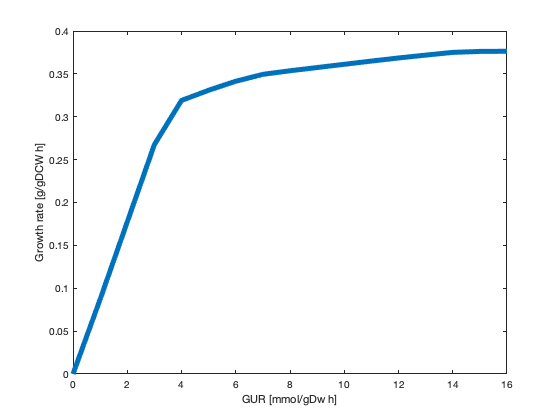

plot2D(GURatesEC,gRatesEC,'','GUR [mmol/gDw h]','Growth rate [g/gDCW h]',false)

## Growth on diverse environments

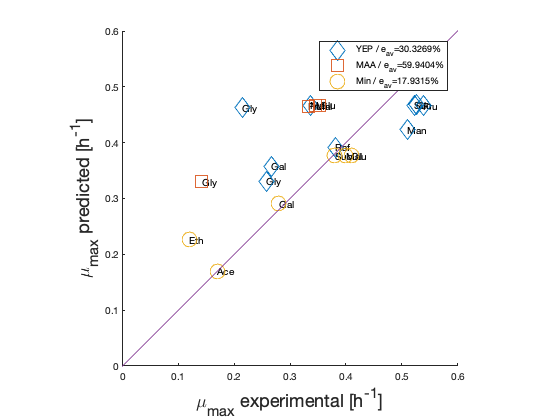

%Simulate growth on diverse environments using different media composition
%and different carbon sources. No numerical constraints are set by the
%Csources_simulations function
[flux_dist, conditions] = Csources_simulations(ecModel);
hold off

## Simulate Crabtree-effect

Csource_id   = ecModel.rxns(glucIndexEC);
ecModel_pool = changeMedia_batch(ecModel,c_source,'Min');
%The name of the exchange reaction that supplies the model with carbon (rxnNames)
oxyIndex    = find(strcmpi(ecModel.rxnNames,'oxygen exchange (reversible)'));
CO2Index    = find(strcmpi(ecModel.rxnNames,'carbon dioxide exchange'));
ethIndex    = find(strcmpi(ecModel.rxnNames,'ethanol exchange'));
aceIndex    = find(strcmpi(ecModel.rxnNames,'acetate exchange'));
exchIndexes = [find(glucIndexEC);oxyIndex;CO2Index;ethIndex;aceIndex];
%Rxn Id for biomass pseudoreaction
bioRxn   = 'r_4041';
%Set growth as objective function
ecModel_pool = setParam(ecModel_pool,'obj',{bioRxn},1);
solution     = solveLP(ecModel_pool,1);
if ~isempty(solution.f)
    maxGrowth = solution.x(strcmpi(ecModel_pool.rxns,bioRxn));
    disp(['The maximum growth rate for the ecModel on ' c_source ' minimal media is: ' num2str(maxGrowth) ' [g/gDw h]'])
end

The maximum growth rate for the ecModel on D-glucose exchange (reversible) minimal media is: 0.37682 [g/gDw h]



i=0;
results = [];
for subopt_growth=0:(maxGrowth/50):maxGrowth
    tempModel = ecModel_pool;
    %Fix suboptimal growth rate
    tempModel = setParam(tempModel,'lb',{bioRxn},0.9999*subopt_growth);
    %Set minimization of glucose uptake as objective function
    tempModel = setParam(tempModel,'obj',Csource_id,-1);
    solution  = solveLP(tempModel);
    if ~isempty(solution.f)
        %Fix optimal glucose uptake and set protein usage as objective to 
        %minimize
        tempModel = setParam(tempModel,'lb',Csource_id,0.9999*solution.x(glucIndexEC));
        tempModel = setParam(tempModel,'ub',Csource_id,1.0001*solution.x(glucIndexEC));
        tempModel = setParam(tempModel,'ub',ecModel.rxns(aceIndex),1);
        %Set minimization of total protein usage as objective function
        tempModel = setParam(tempModel,'obj',{'prot_pool_exchange'},-1);
        %Solve!
        solution  = solveLP(tempModel,1);
        if ~isempty(solution.f)
            exchangeVector = solution.x(exchIndexes);
            newRow  = [subopt_growth, exchangeVector'];
            results = [results; newRow];
        end
    end 
    i = i+1;
end
%Plot results
names = {'Glucose' 'Oxygen' 'CO2' 'Ethanol' 'Acetate'};
for i=1:(length(exchIndexes))
    plot(results(:,1),results(:,i+1),'LineWidth',3)
    hold on
end
legend(names)
xlabel('Dilution rate [1/h]','FontSize',18)
ylabel('Exchange fluxes [mmol/gDw h]','FontSize',18)
xlim([0 max(results(:,1))])